# modeling growth of k. rhaeticus, consumption of glucose, and synthesis of bacterial cellulose: part 1 of 2

this script fits the parameters of the monod equation and mass-balance ODEs to experimental data via parameter estimation (inverse modeling) as described in section 3 of my thesis

% created 01/07/2026 12:49
% last edited 05/05/2026 14:22

### inputs & outputs

% input: experimental data. load in the file "workspace_6well.mat". 
% it contains lots of column vectors. if you line up all these column 
% vectors next to eachother in a grid, it would make sense as a spreadsheet.
%       dayno - day number of the experiment (starts on 0)
%       pellm - pellicle mass (g) measured with thickness (mm) as a proxy
%       gluc - glucose in the media (g/L) measured with blood glucometer
%       and calibrated per experiment
%       OD - optical density (OD600) of the media measured with spectrophotometer
% this experiment has two sets of intial conditions: one for A, B, and C,
% and the other for D, E, and F
% output: fitted parameters - mu_max, Ks, alpha, beta, ms, Yxs, Yps, gamma,
% k_pH, eta - and graphs

### plot colors

RGB = orderedcolors("gem");
gem_blue = RGB(1,:);
gem_red = RGB(2,:);
gem_orange = RGB(3,:);
gem_purple = RGB(4,:);
gem_green = RGB(5,:);
gem_teal = RGB(6,:);
gem_pink = RGB(7,:);

### pellicle mass over time

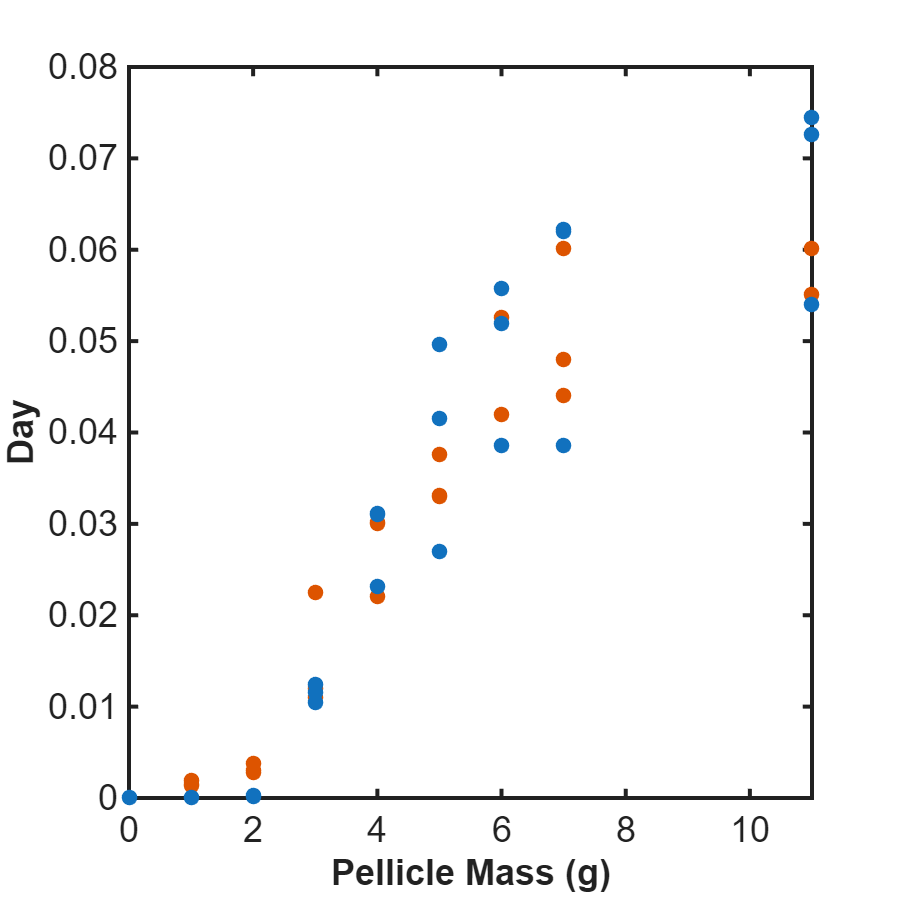

scatter(dayno,pellmA,60,gem_red,'filled','o');
hold on;

scatter(dayno,pellmB,60,gem_red,'filled','o');
scatter(dayno,pellmC,60,gem_red,'filled','o');
scatter(dayno,pellmD,60,gem_blue,'filled','o');
scatter(dayno,pellmE,60,gem_blue,'filled','o');
scatter(dayno,pellmF,60,gem_blue,'filled','o');

xlabel('Pellicle Mass (g)');
ylabel('Day');
improvePlot();
hold off;

### media glucose levels over time

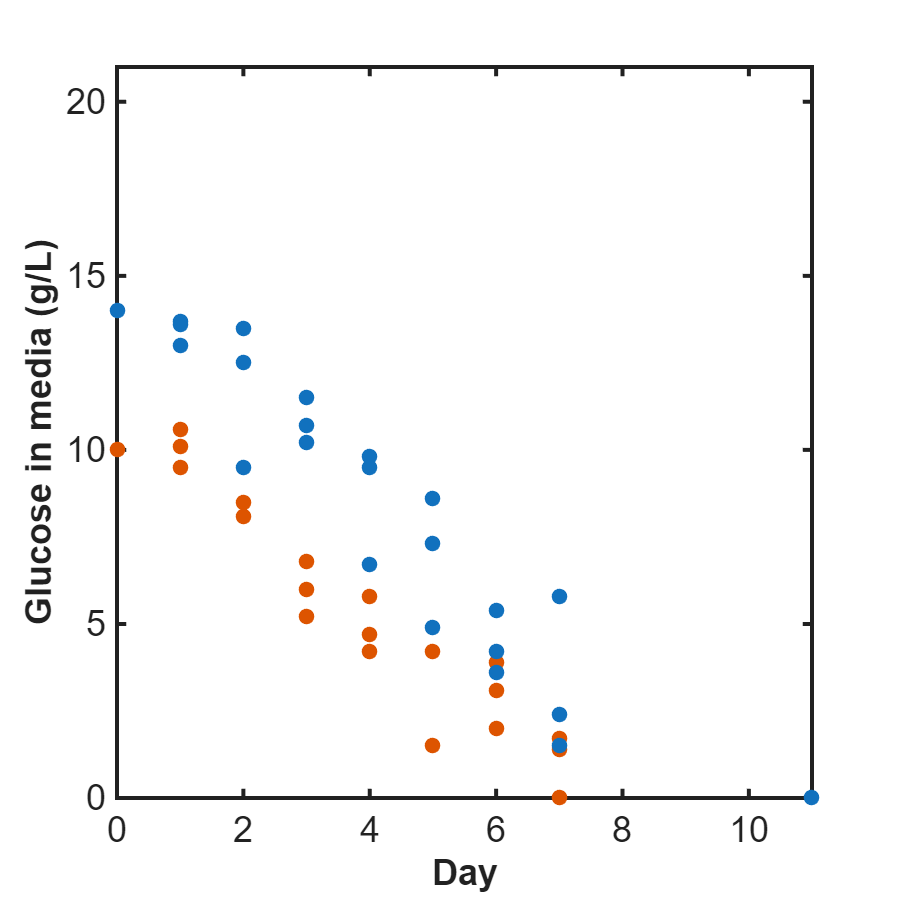

scatter(dayno,glucA,60,gem_red,'filled','o')
hold on;

scatter(dayno,glucB,60,gem_red,'filled','o');
scatter(dayno,glucC,60,gem_red,'filled','o');
scatter(dayno,glucD,60,gem_blue,'filled','o');
scatter(dayno,glucE,60,gem_blue,'filled','o');
scatter(dayno,glucF,60,gem_blue,'filled','o');

xlabel('Day');
ylabel('Glucose in media (g/L)');
ylim([0 21]);
improvePlot();
hold off;

### OD600 over time

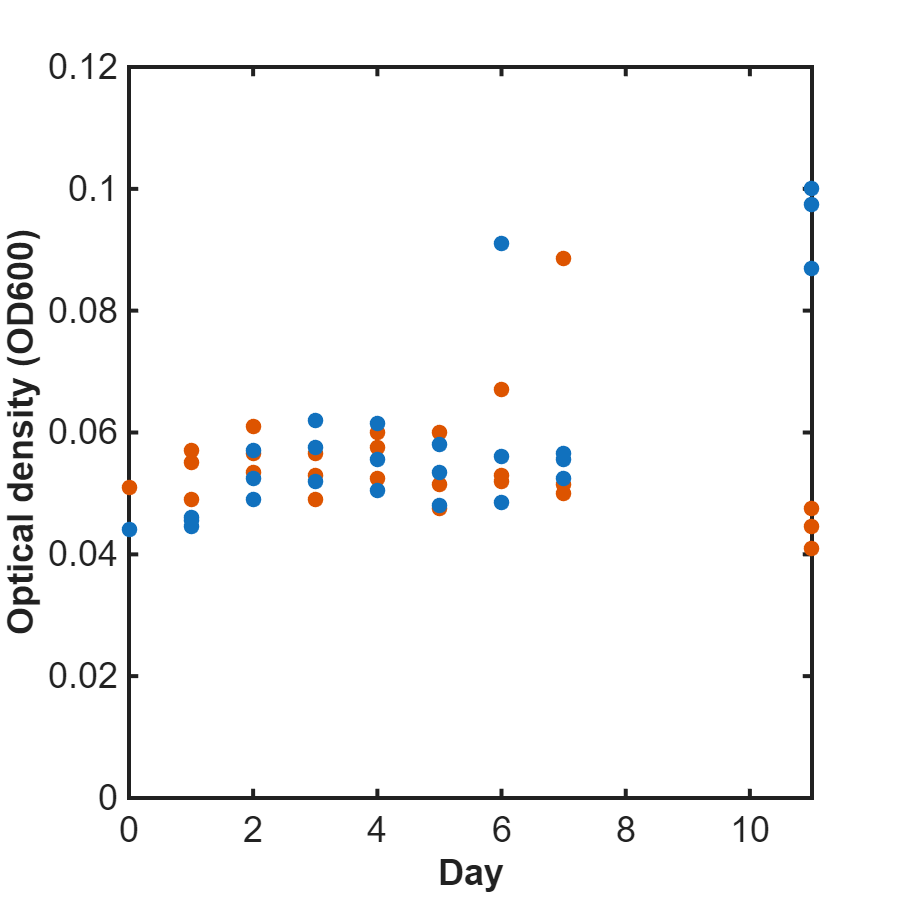

scatter(dayno,ODA,60,gem_red,'filled','o')
hold on;

scatter(dayno,ODB,60,gem_red,'filled','o');
scatter(dayno,ODC,60,gem_red,'filled','o');
scatter(dayno,ODD,60,gem_blue,'filled','o');
scatter(dayno,ODE,60,gem_blue,'filled','o');
scatter(dayno,ODF,60,gem_blue,'filled','o');

xlabel('Day');
ylabel('Optical density (OD600)');
ylim([0 0.12]);
improvePlot();
hold off;

### turning data into the units and formats needed

% I am going to merge A, B, and C into one dataset

tData = [dayno;dayno;dayno]; % units: days

XDataOD = [ODD;ODE;ODF]; % units: OD600
ODtobiomass_factor = 1; % (typical: 0.2-0.5, idk for my culture)
XData = XDataOD * ODtobiomass_factor;

SData = [glucD;glucE;glucF]; % units: g/L

vol = 0.01; % units: L (10 mL per each of 6 tubes)
PDatag = [pellmD;pellmE;pellmF]; % units: g
PData = PDatag/vol; % units: g/L 

[tData,idx] = sort(tData);
XData = XData(idx);
SData = SData(idx);
PData = PData(idx);

% have to get rid of all the 0s at the start of PData so that the graph
% doesn't turn out totally flat
PData(1:6,1) = 1e-4;

% checking that this all worked out
allData = [tData, XData, SData, PData]

allData =          0    0.0440   14.0000    0.0001
         0    0.0440   14.0000    0.0001
         0    0.0440   14.0000    0.0001
    1.0000    0.0455   13.0000    0.0001
    1.0000    0.0460   13.7000    0.0001
    1.0000    0.0445   13.6000    0.0001
    2.0000    0.0570    9.5000    0.0200
    2.0000    0.0525   12.5000    0.0300
    2.0000    0.0490   13.5000    0.0300
    3.0000    0.0575   10.2000    1.1600
    3.0000    0.0620   11.5000    1.0400
    3.0000    0.0520   10.7000    1.2400
    4.0000    0.0615    6.7000    2.3100
    4.0000    0.0505    9.8000    3.1100
    4.0000    0.0555    9.5000    3.1000


### fitting parameters

y0 = [XData(1); PData(1); tData(1)];

% weights 
wX = 1/mean(XData); 
wS = 1/mean(SData);
wP = 1/mean(PData); 

% initial guess and bounds [mu_max, Ks, alpha, beta, ms, Yxs, Yps, gamma, k_pH, eta]
%                    mu_max   Ks     alpha  beta    ms     Yxs       Yps    gamma  k_pH   eta
theta0 = [           0.5,     10,   3,      0.5,    0.1,   0.003,    0.55,  15,    5,     0.29 ];
lb     = [           0.2,     5,    0.5,    0,      0.0,   0.0005,   0.20,  10,    15,    0.10 ];
ub     = [           0.6,     20,   20,     20,      0.5,   0.015,    0.90,  20,    20,    0.50 ];
fun = @(th) residuals(th, tData, XData, SData, PData, y0, wX, wS, wP);

opts = optimoptions('lsqnonlin','Display','iter','MaxFunctionEvaluations',2000);
theta_hat = lsqnonlin(fun, theta0, lb, ub, opts);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0         11           56.3286                             74.1
     1         22           56.3286         2.98294             74.1      
     2         33           40.9141        0.745736             52.7      
     3         44           18.5088         1.49147             22.9      
     4         55           18.5088         1.82391             22.9      
     5         66           14.2891        0.455978             17.3      
     6         77           9.80938        0.911956             9.77      
     7         88           9.80938        0.348112             9.77      
     8         99           9.26975       0.0870279             8.71      
     9        110           9.26975        0.174056             8.71      
    10        121           9.26975       0.0435139             8.71      
    11        132           9.26975      

% figure;
% plot(tfineS, PfineS, 'b.-');
% xlabel('t (days)'); ylabel('P raw from ODE');
% title('Raw P vs t before interpolation');

### forward simulation and plots

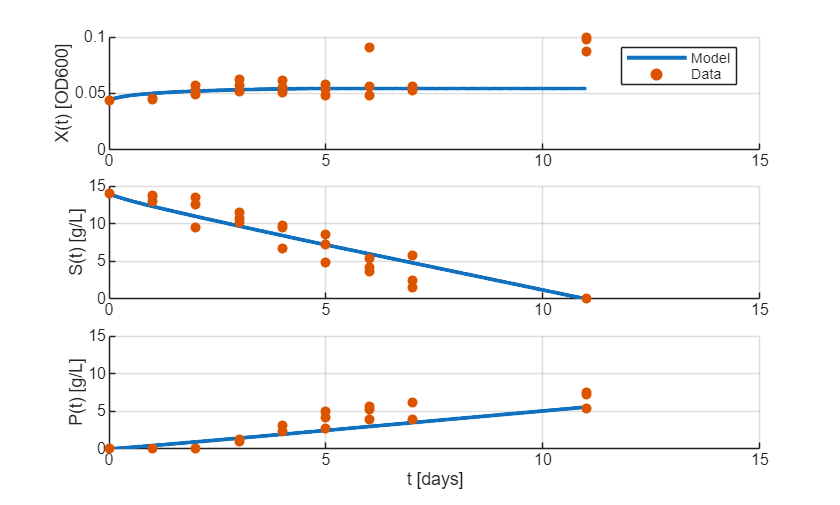

%% after lsqnonlin returns theta_hat, forward simulation + plots

% simulate model on a dense S-grid, then convert to t-grid
t0 = min(tData);
tf = 28;

S0 = SData(1);

% build a dense S-grid from initial substrate down to 0
S_end = 0;
SFine = linspace(S0, S_end, 2000);

ode = @(S, y) rhs_S(S, y, theta_hat, S0);

optsODE = odeset('RelTol', 1e-8, 'AbsTol', 1e-10);
solS = ode15s(ode, [S0 S_end], y0, optsODE);

YfineS = deval(solS, SFine);   % rows = [X; P; t]
XfineS = YfineS(1, :)';
PfineS = YfineS(2, :)';
tfineS = YfineS(3, :)';

% remove non-finite points if needed
maskFine = isfinite(XfineS) & isfinite(PfineS) & isfinite(tfineS) & isfinite(SFine(:));
XfineS = XfineS(maskFine);
PfineS = PfineS(maskFine);
tfineS = tfineS(maskFine);
SfineValid = SFine(maskFine)';

% sort by t to interpolate onto a uniform t-grid
[tfineSorted, idxSort] = sort(tfineS);
Xsorted = XfineS(idxSort);
Psorted = PfineS(idxSort);
Ssorted = SfineValid(idxSort);

% remove duplicate t values for interp1
[tfineUnique, ia] = unique(tfineSorted);
Xunique = Xsorted(ia);
Punique = Psorted(ia);
Sunique = Ssorted(ia);

% dense time vector
tFine = linspace(min(tfineUnique), max(tfineUnique), 1000)';

% interpolate solution onto time axis
Xfit = interp1(tfineUnique, Xunique, tFine, 'pchip', NaN);
Sfit = interp1(tfineUnique, Sunique, tFine, 'pchip', NaN);
Pfit = interp1(tfineUnique, Punique, tFine, 'pchip', NaN);

% [min(tfineUnique) max(tfineUnique)]
% sum(isfinite(Xfit))
% sum(isfinite(Sfit))
% sum(isfinite(Pfit))

% evaluate model at data times
Xhat = interp1(tfineUnique, Xunique, tData, 'pchip', NaN);
Shat = interp1(tfineUnique, Sunique, tData, 'pchip', NaN);
Phat = interp1(tfineUnique, Punique, tData, 'pchip', NaN);

%% PLOT
figure;
tiledlayout(3,1,"TileSpacing","compact");

% X
nexttile; hold on; grid on;
plot(tFine, Xfit, 'LineWidth', 2);
scatter(tData, XData, 25, 'filled');
ylabel('X(t) [OD600]');
ylim([0 0.1]);
xlim([0 15]);
legend('Model', 'Data', 'Location', 'best');

% S
nexttile; hold on; grid on;
plot(tFine, Sfit, 'LineWidth', 2);
scatter(tData, SData, 25, 'filled');
ylabel('S(t) [g/L]');
ylim([0 15]);
xlim([0 15]);

% P
nexttile; hold on; grid on;
plot(tFine, Pfit, 'LineWidth', 2);
scatter(tData, PData, 25, 'filled');
ylabel('P(t) [g/L]');
xlabel('t [days]');
ylim([0 15]);
xlim([0 15]);

%% fit quality metrics 
rXn = wX*(Xhat - XData);
rSn = wS*(Shat - SData);
rPn = wP*(Phat - PData);

nrmseX = sqrt(mean((wX*(Xhat - XData)).^2));
nrmseS = sqrt(mean((wS*(Shat - SData)).^2));
nrmseP = sqrt(mean((wP*(Phat - PData)).^2));

fprintf('NRMSE: X=%.3f, S=%.3f, P=%.3f\n', nrmseX, nrmseS, nrmseP);

NRMSE: X=0.271, S=0.183, P=0.485


%% print parameters
mu_max = theta_hat(1);
Ks     = theta_hat(2);
alpha  = theta_hat(3);
beta   = theta_hat(4);
ms     = theta_hat(5);
Yxs    = theta_hat(6);
Yps    = theta_hat(7);
gamma  = theta_hat(8);
k_pH   = theta_hat(9);
eta    = theta_hat(10);

k11 = 1 / Yxs + alpha / Yps;
k12 = beta / Yps + ms;

fprintf('Fitted params:\n');

Fitted params:


fprintf('  mu_max = %.6g\n', mu_max);

  mu_max = 0.571873


fprintf('  K_S    = %.6g\n', Ks);

  K_S    = 6.93295


fprintf('  alpha  = %.6g\n', alpha);

  alpha  = 0.602013


fprintf('  beta   = %.6g\n', beta);

  beta   = 9.47756


fprintf('  m_s    = %.6g\n', ms);

  m_s    = 0.200211


fprintf('  Yxs    = %.6g\n', Yxs);

  Yxs    = 0.00972188


fprintf('  Yps    = %.6g\n', Yps);

  Yps    = 0.434737


fprintf('  gamma  = %.6g\n', gamma);

  gamma  = 11.9936


fprintf('  k_pH   = %.6g\n', k_pH);

  k_pH   = 17.339


fprintf('  eta    = %.6g\n', eta);

  eta    = 0.1443


fprintf('Derived:\n');

Derived:


fprintf('  k11    = %.6g\n', k11);

  k11    = 104.246


fprintf('  k12    = %.6g\n', k12);

  k12    = 22.0009


### functions

#### ode rhs

%% ode rhs with S as independent variable
function dydS = rhs_S(S, y, theta, S0)
    % state vector:
    % y(1) = X(S)
    % y(2) = P(S)
    % y(3) = t(S)

    X = y(1);
    P = y(2);
    % t = y(3); % not needed explicitly

    mu_max = theta(1);
    Ks     = theta(2);
    alpha  = theta(3);
    beta   = theta(4);
    ms     = theta(5);
    Yxs    = theta(6);
    Yps    = theta(7);
    gamma  = theta(8);
    k_pH   = theta(9);
    eta    = theta(10);

    % fixed constants
    pH0    = 5.9;
    pHcrit = 5.0;

    % effective nonnegative substrate for Monod
    S_eff = max(S, 0);

    % pH model: pH(t) = pH0 - eta*(S0 - S)
    pH = pH0 - eta * (S0 - S_eff);
    
    % logistic pH inhibition term
    f_pH = 1 / (1 + exp(k_pH * (pHcrit - pH)));

    % oxygen product inhibition term
    f_P = 1 / (1 + gamma * max(P, 0));

    mu = mu_max * (S_eff / (Ks + S_eff)) * f_P * f_pH;

    k11 = 1 / Yxs + alpha / Yps;
    k12 = beta / Yps + ms;

    denom = k11 * mu + k12;

    % guard against division by zero / negative states
    if ~isfinite(mu) || ~isfinite(denom) || denom <= 0 || X <= 0 || ~isfinite(X)
        dydS = [0; 0; 0];
        return
    end

    dX_dS = -mu / denom;
    dP_dS = -(alpha * mu + beta) / denom;
    dt_dS = -1 / (denom * X);

    dydS = [dX_dS; dP_dS; dt_dS];
end

#### residual function (integrate and compare to data)

%% residual function 
function r = residuals(theta, tData, XData, SData, PData, y0, wX, wS, wP)

    % columnize + remove NaNs
    tData = tData(:);
    XData = XData(:);
    SData = SData(:);
    PData = PData(:);

    mask = isfinite(tData) & isfinite(XData) & isfinite(SData) & isfinite(PData);
    tData = tData(mask);
    XData = XData(mask);
    SData = SData(mask);
    PData = PData(mask);

    % sort by time
    [tData, idx] = sort(tData);
    XData = XData(idx);
    SData = SData(idx);
    PData = PData(idx);

    % initial conditions from first point
    t0 = tData(1);
    tf = max(tData);
    S0 = SData(1);

    % y0 is [X0; P0; t0]
    y0_local = [y0(1); y0(2); t0];

    ode = @(S, y) rhs_S(S, y, theta, S0);

    % integrate from S0 downward 
    S_end = 0;

    opts = odeset('RelTol', 1e-7, 'AbsTol', 1e-9, 'MaxStep', max((S0 - S_end) / 200, 1e-6));

    try
        sol = ode15s(ode, [S0 S_end], y0_local, opts);

        % sample solution on dense S-grid
        Sgrid = linspace(S0, S_end, 2000);
        Y = deval(sol, Sgrid);

        Xsol = Y(1, :)';
        Psol = Y(2, :)';
        tsol = Y(3, :)';
        Ssol = Sgrid(:);

        % keep optimizer away from unphysical
        if any(~isfinite([Xsol; Psol; tsol])) || any(Xsol <= 0)
            pen = 1e6 * (1 + norm(theta));
            r = pen * ones(3 * numel(tData), 1);
            return
        end

        % sort by t and remove duplicates
        [tsol, idxSort] = sort(tsol);
        Xsol = Xsol(idxSort);
        Psol = Psol(idxSort);
        Ssol = Ssol(idxSort);

        [tsolU, ia] = unique(tsol);
        XsolU = Xsol(ia);
        PsolU = Psol(ia);
        SsolU = Ssol(ia);

        % need coverage up to final experimental time
        if max(tsolU) < tf
            pen = 1e6 * (1 + norm(theta));
            r = pen * ones(3 * numel(tData), 1);
            return
        end

        % interpolate model onto measurement times
        Xhat = interp1(tsolU, XsolU, tData, 'pchip', NaN);
        Shat = interp1(tsolU, SsolU, tData, 'pchip', NaN);
        Phat = interp1(tsolU, PsolU, tData, 'pchip', NaN);

        if any(~isfinite([Xhat; Shat; Phat])) || any(Shat < -1e-6) || any(Xhat < -1e-9)
            pen = 1e6 * (1 + norm(theta));
            r = pen * ones(3 * numel(tData), 1);
            return
        end

        r = [wX * (Xhat - XData);
             wS * (Shat - SData);
             wP * (Phat - PData)];

    catch
        pen = 1e6 * (1 + norm(theta));
        r = pen * ones(3 * numel(tData), 1);
    end
end